# **Project Title: Early Pest Detection using Image Processing**

## Image Classificaton - Training

### Train 1

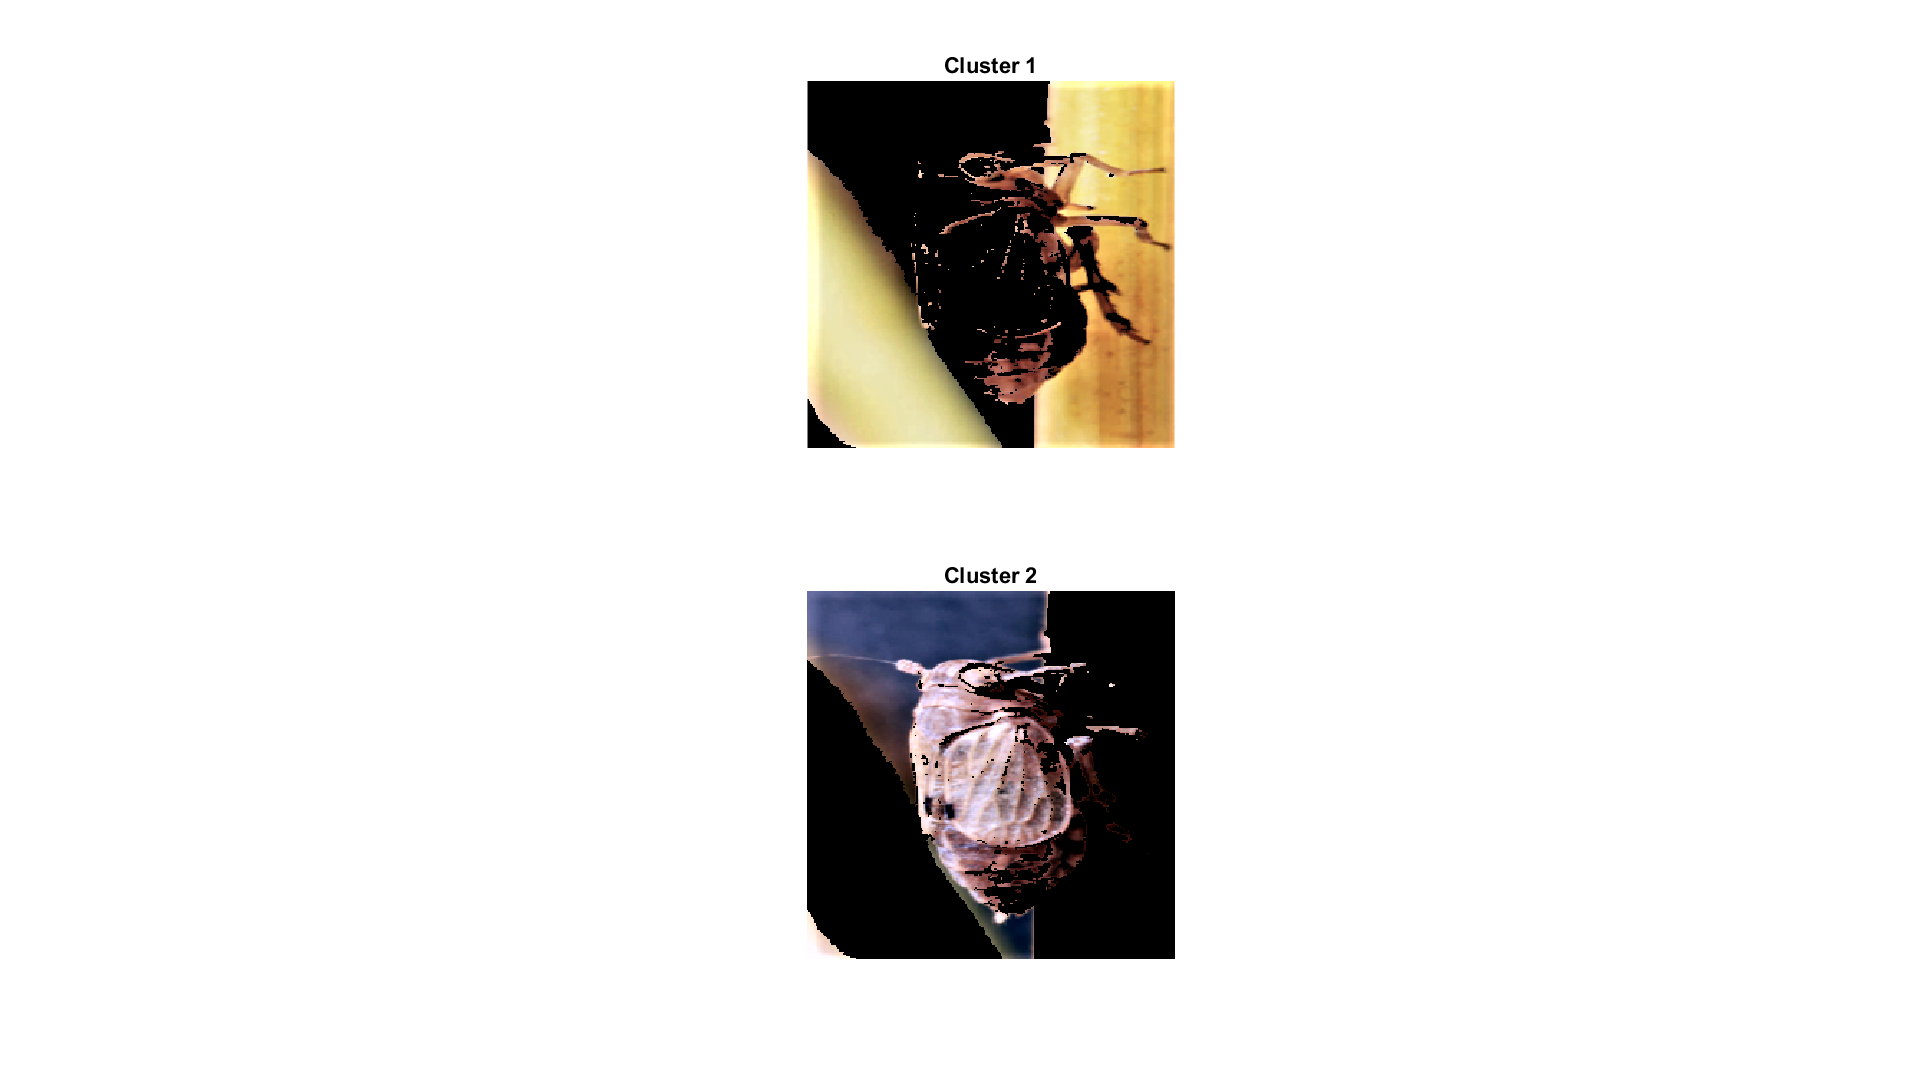

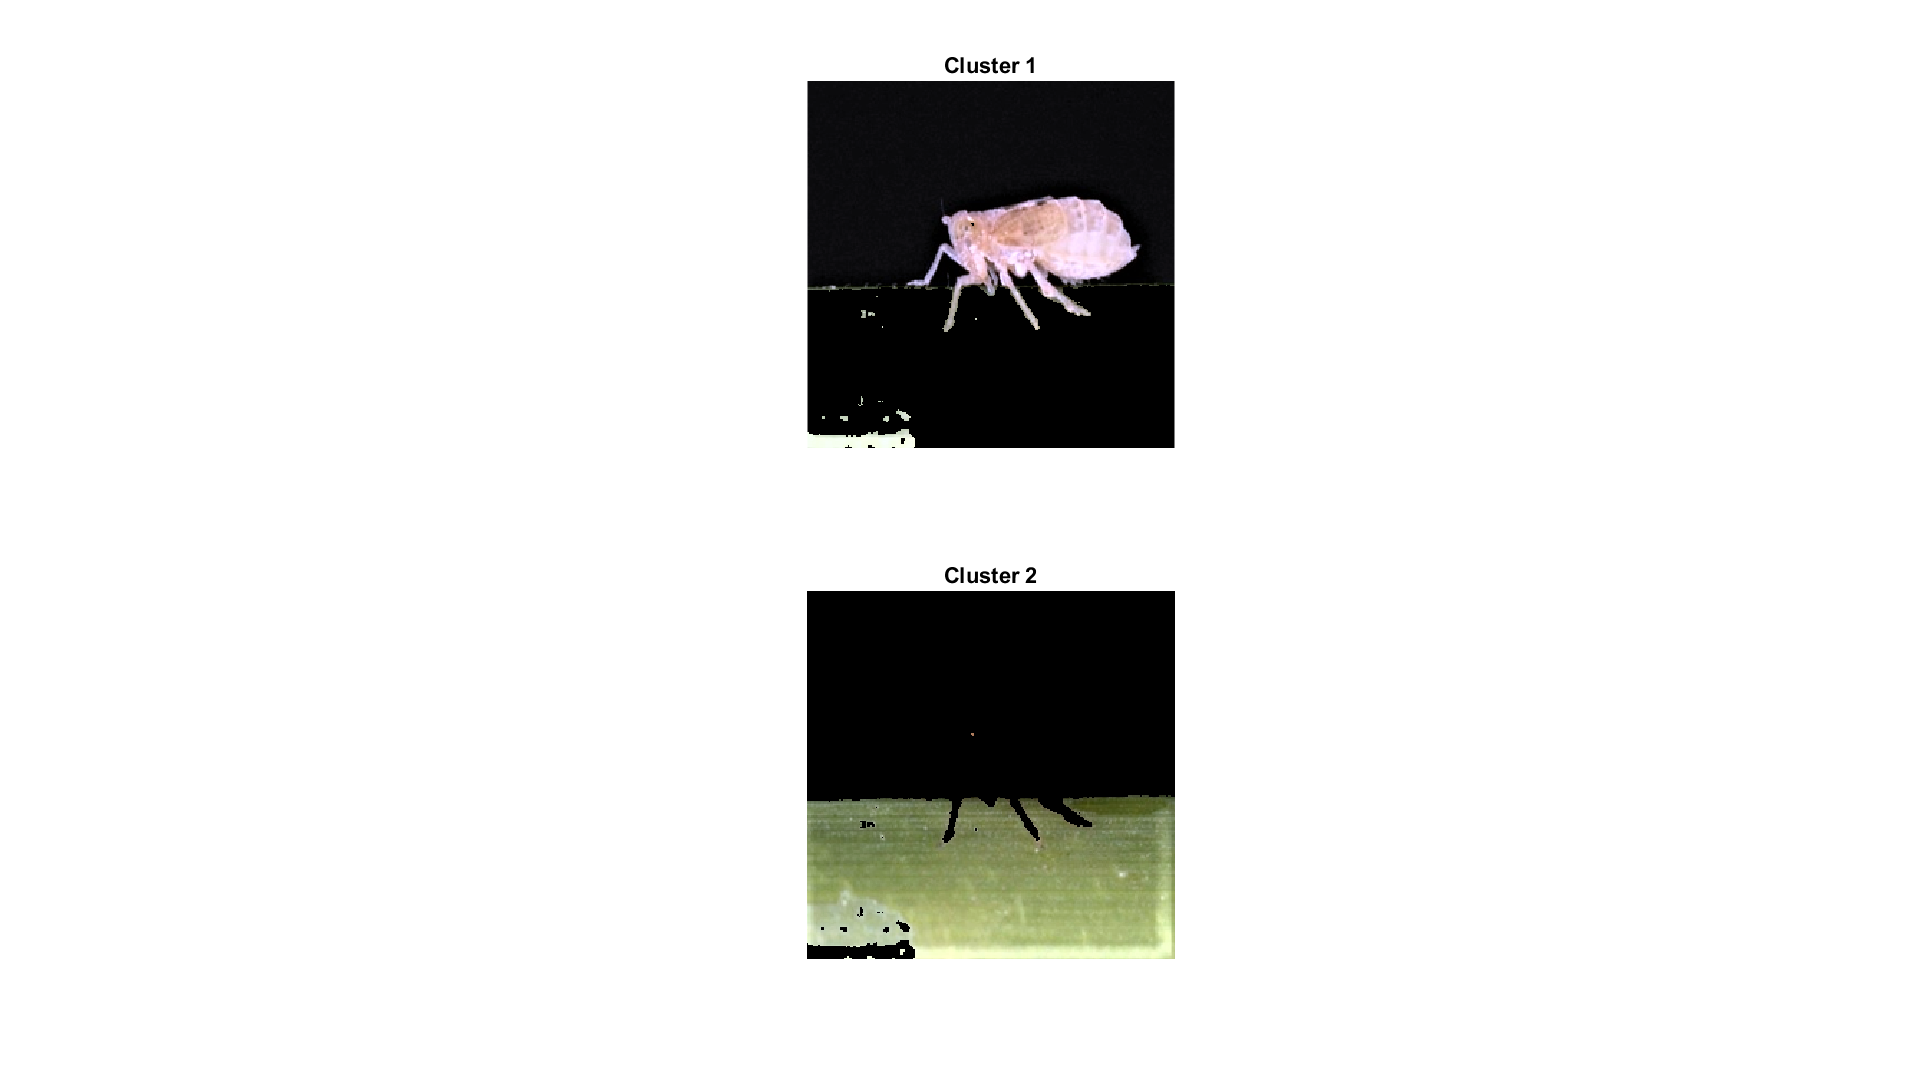

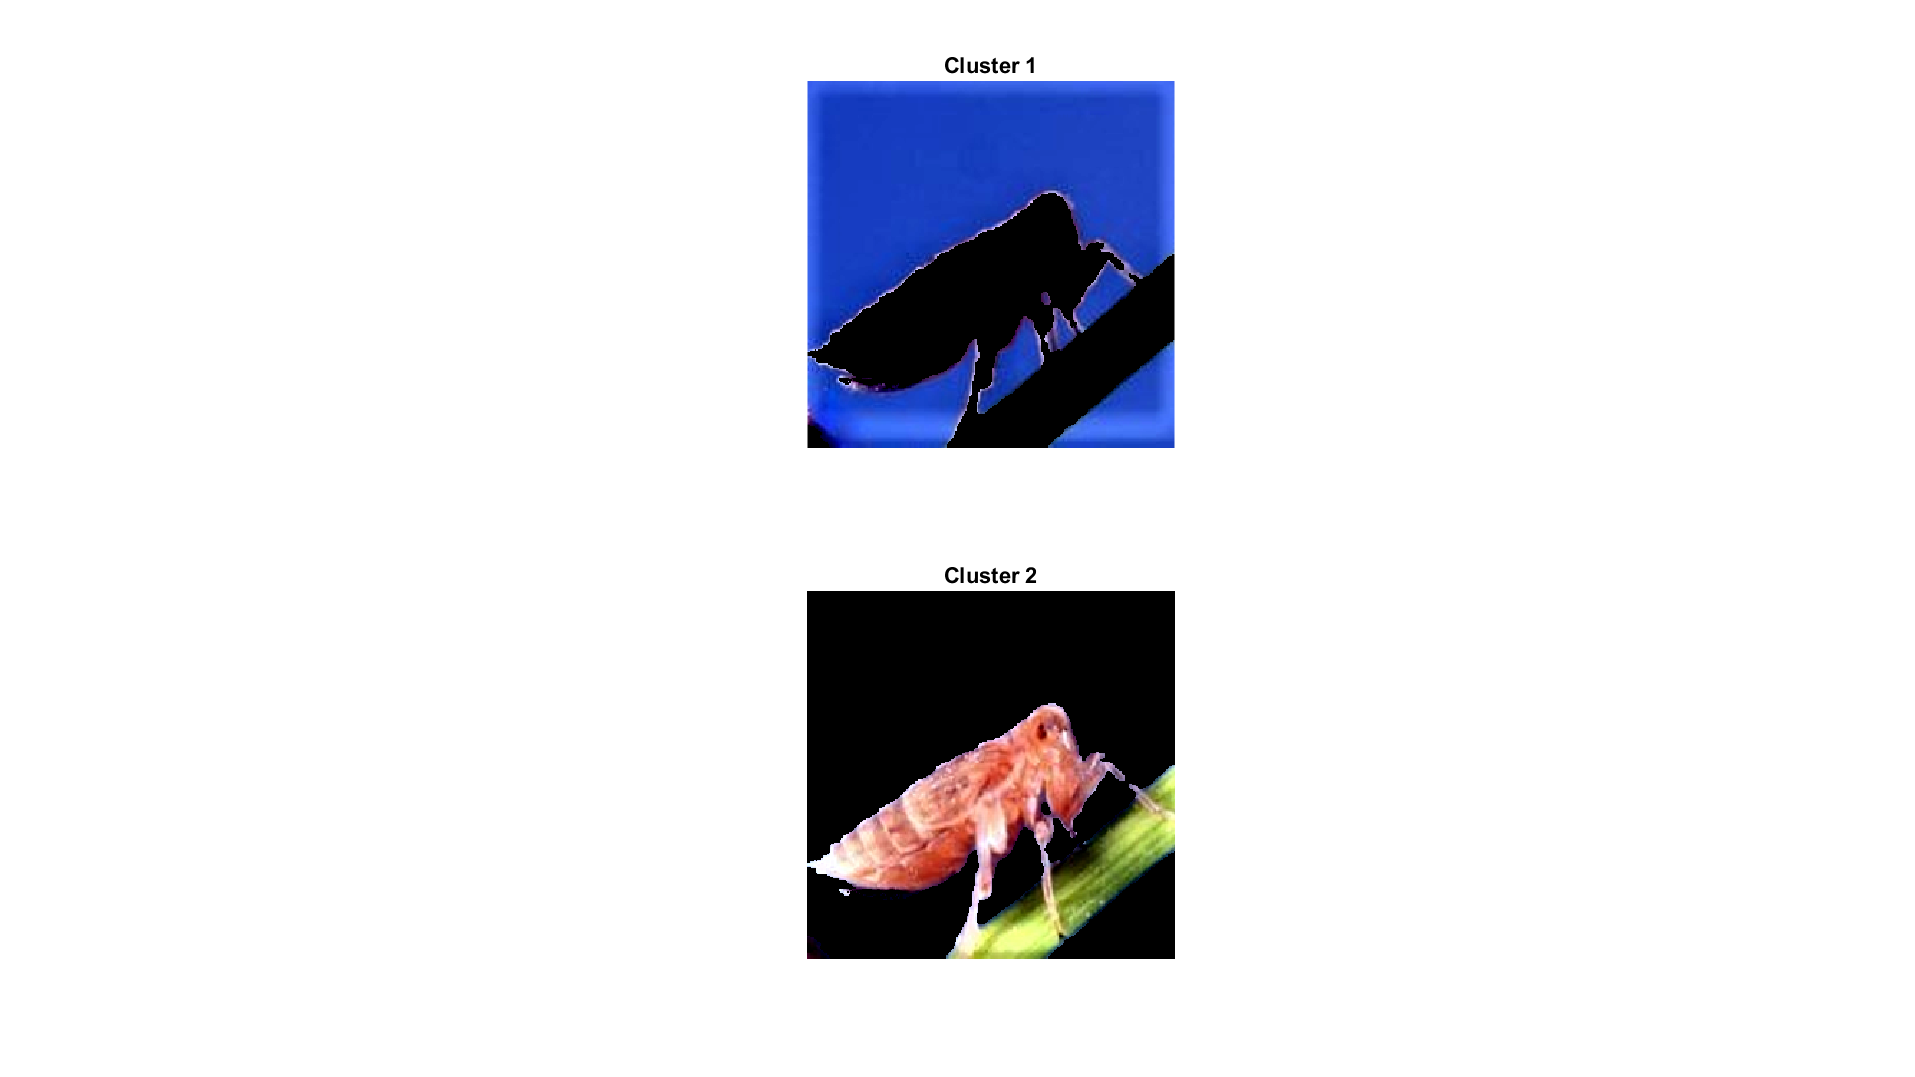

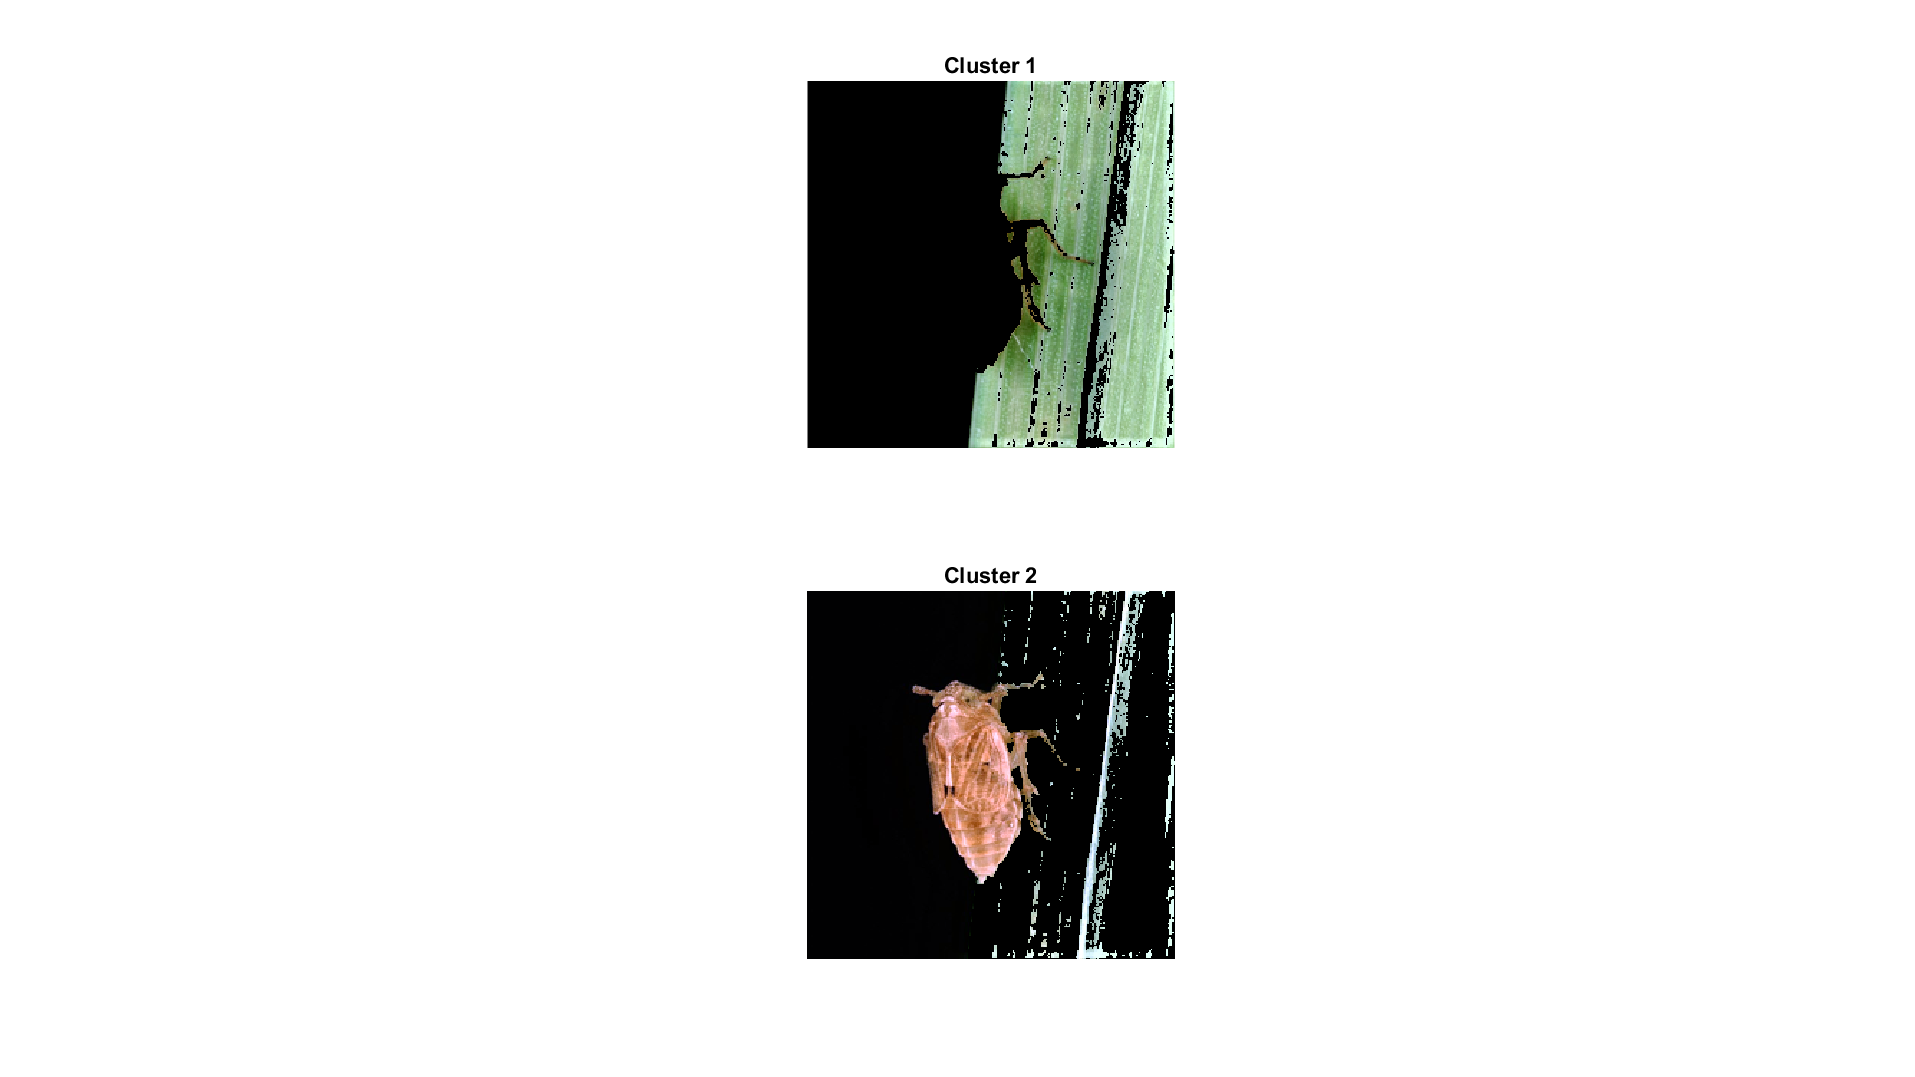

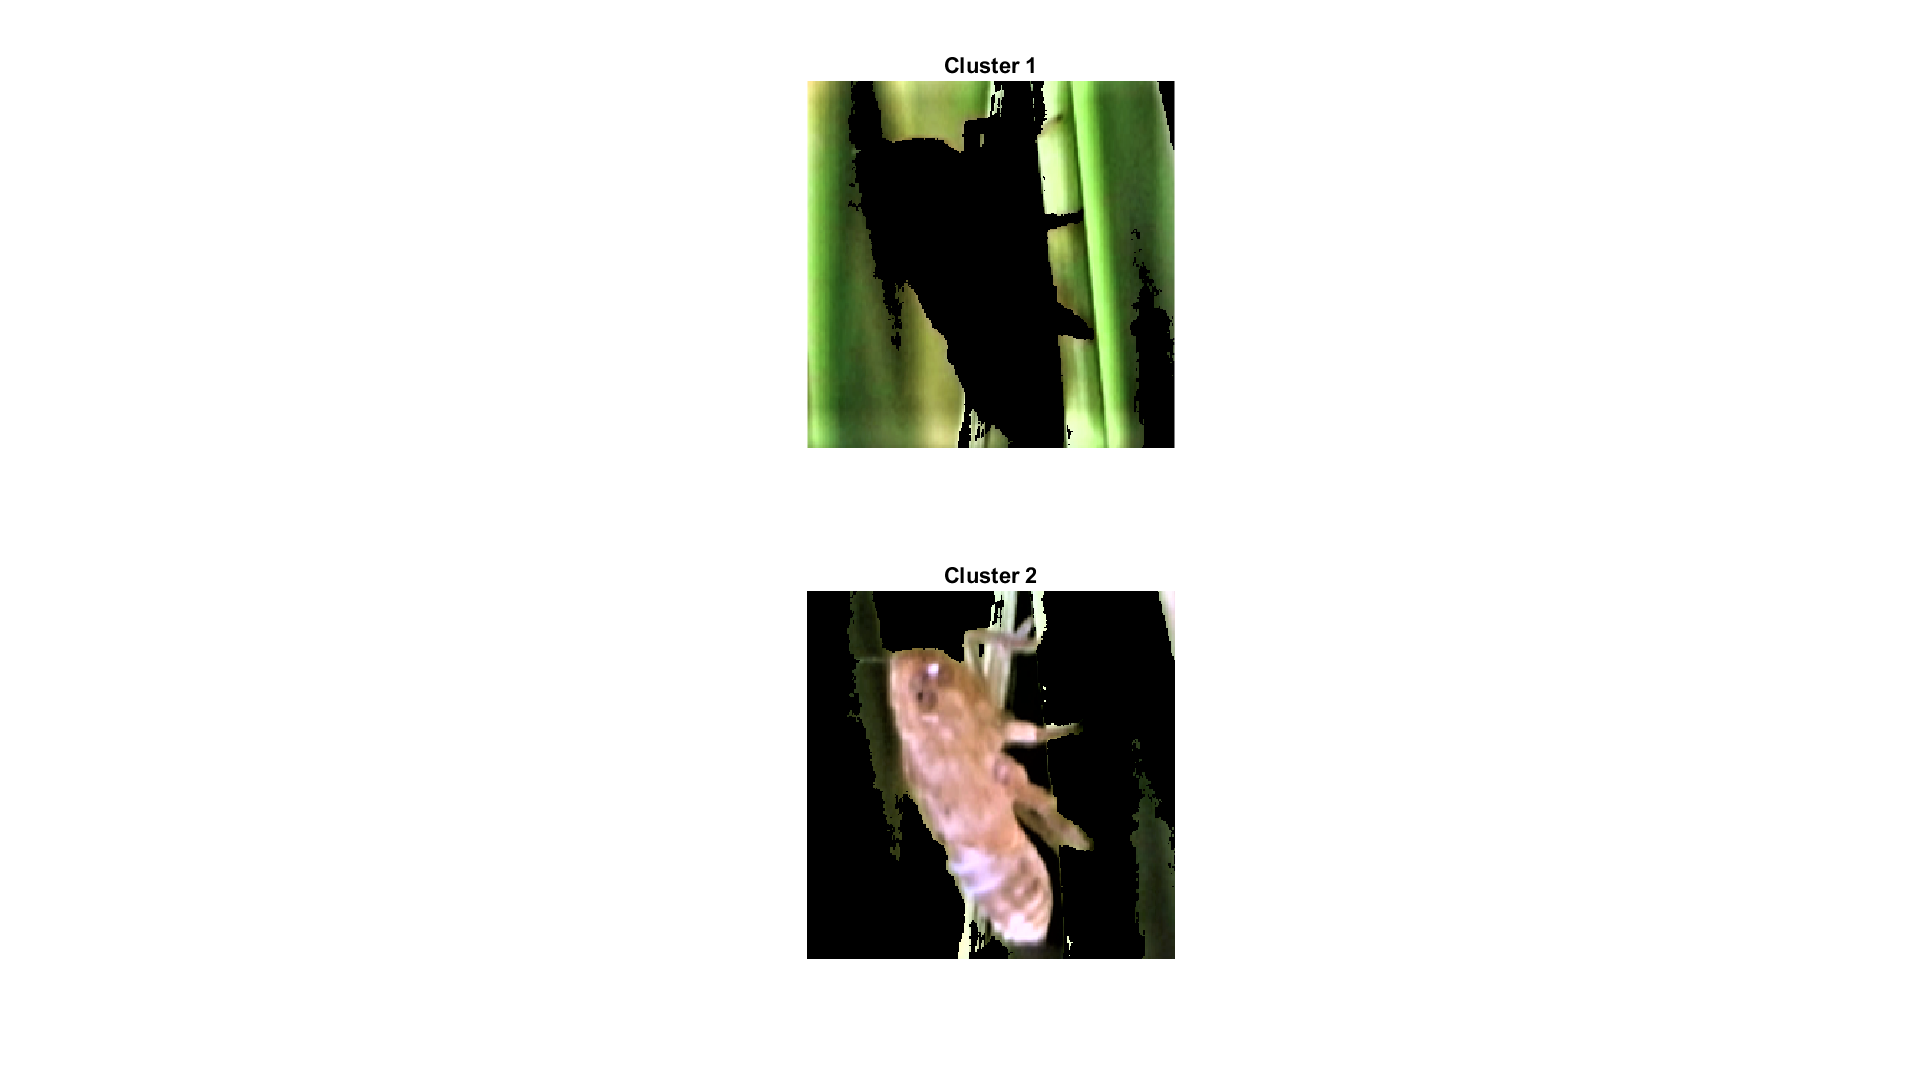

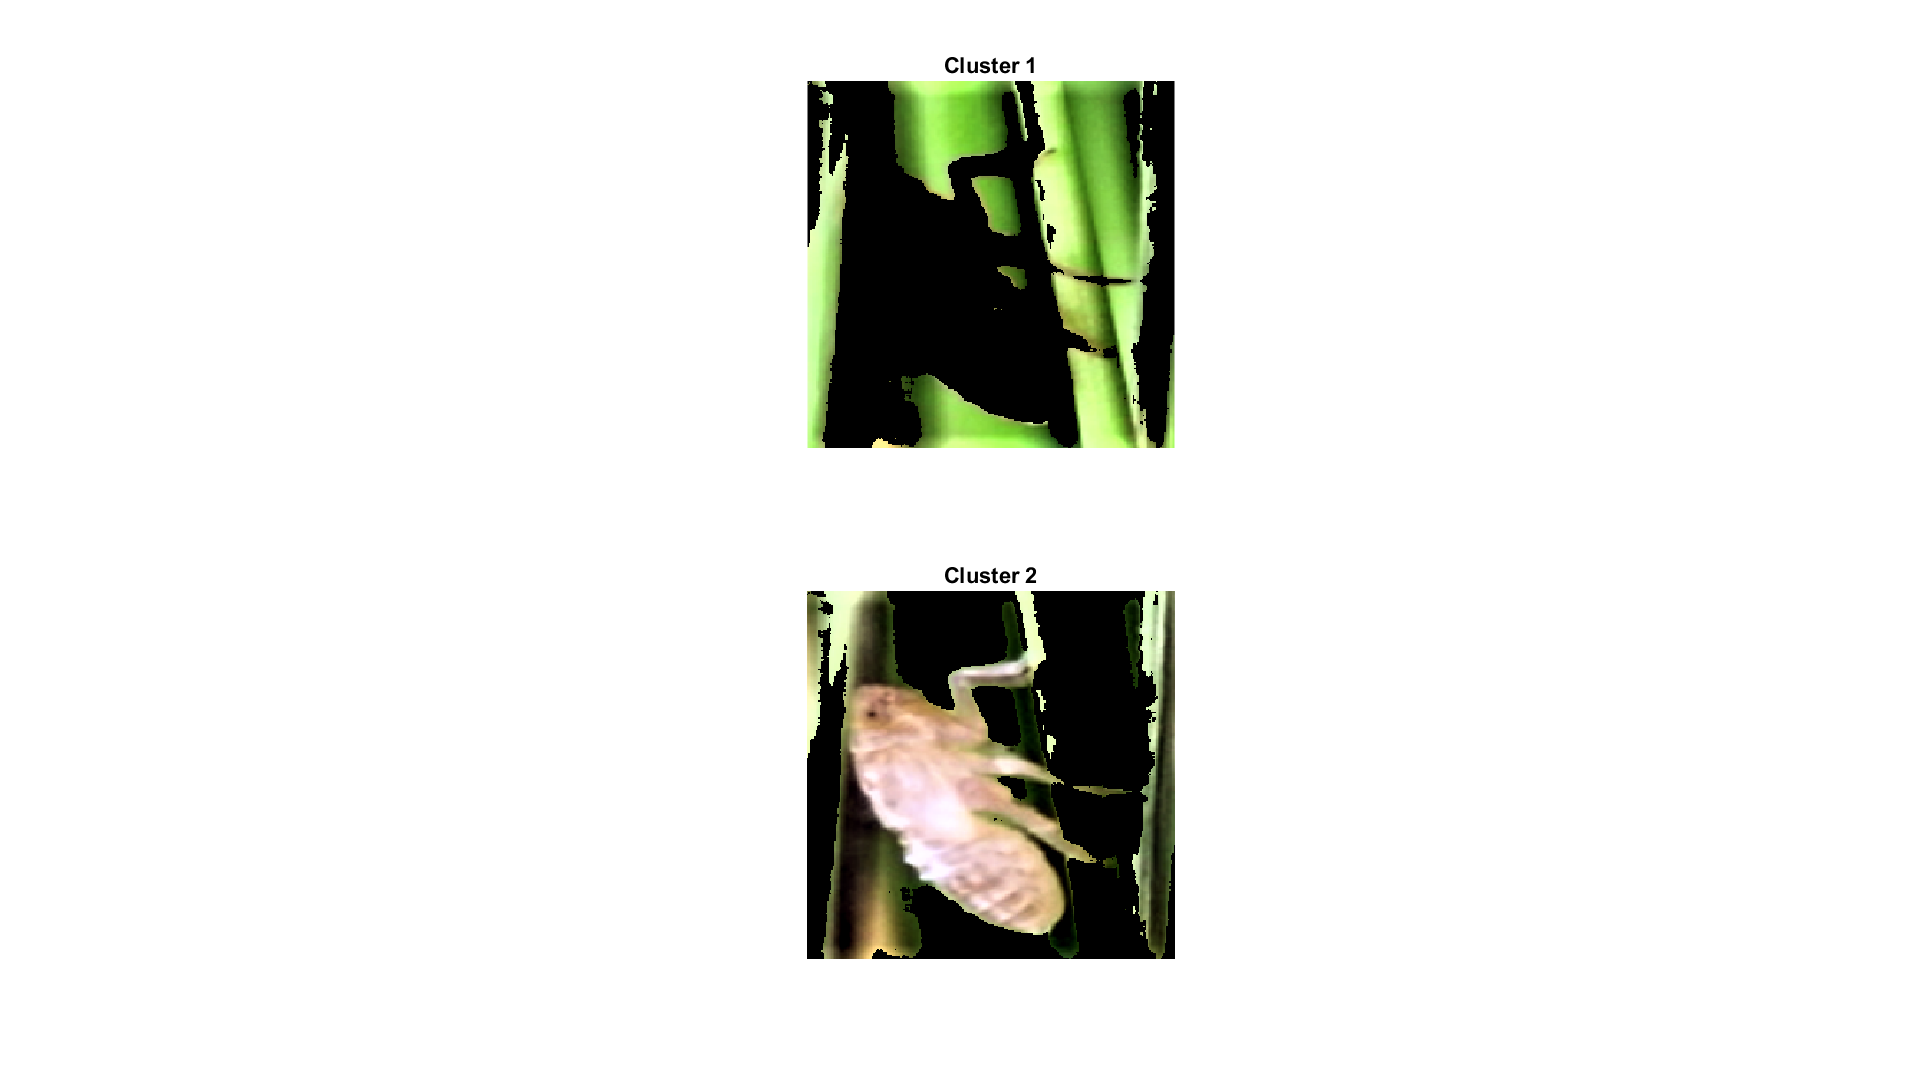

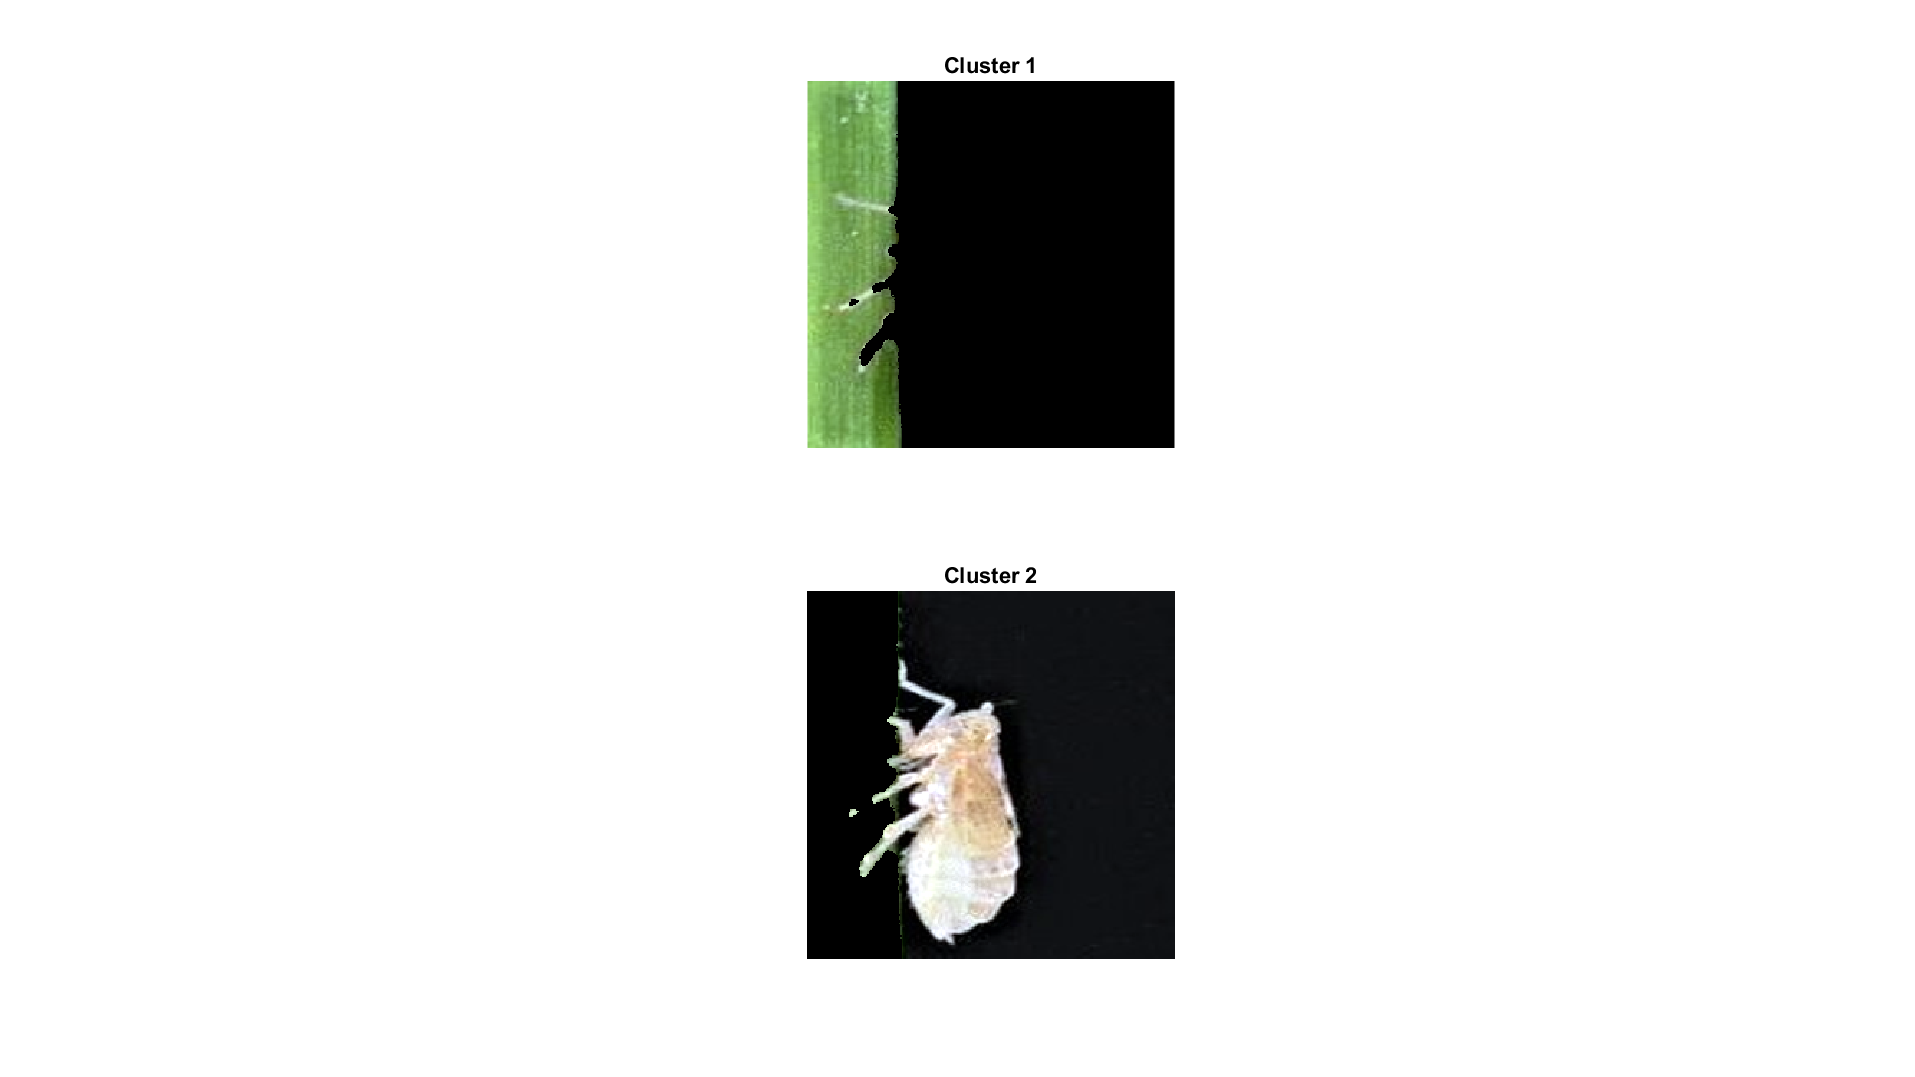

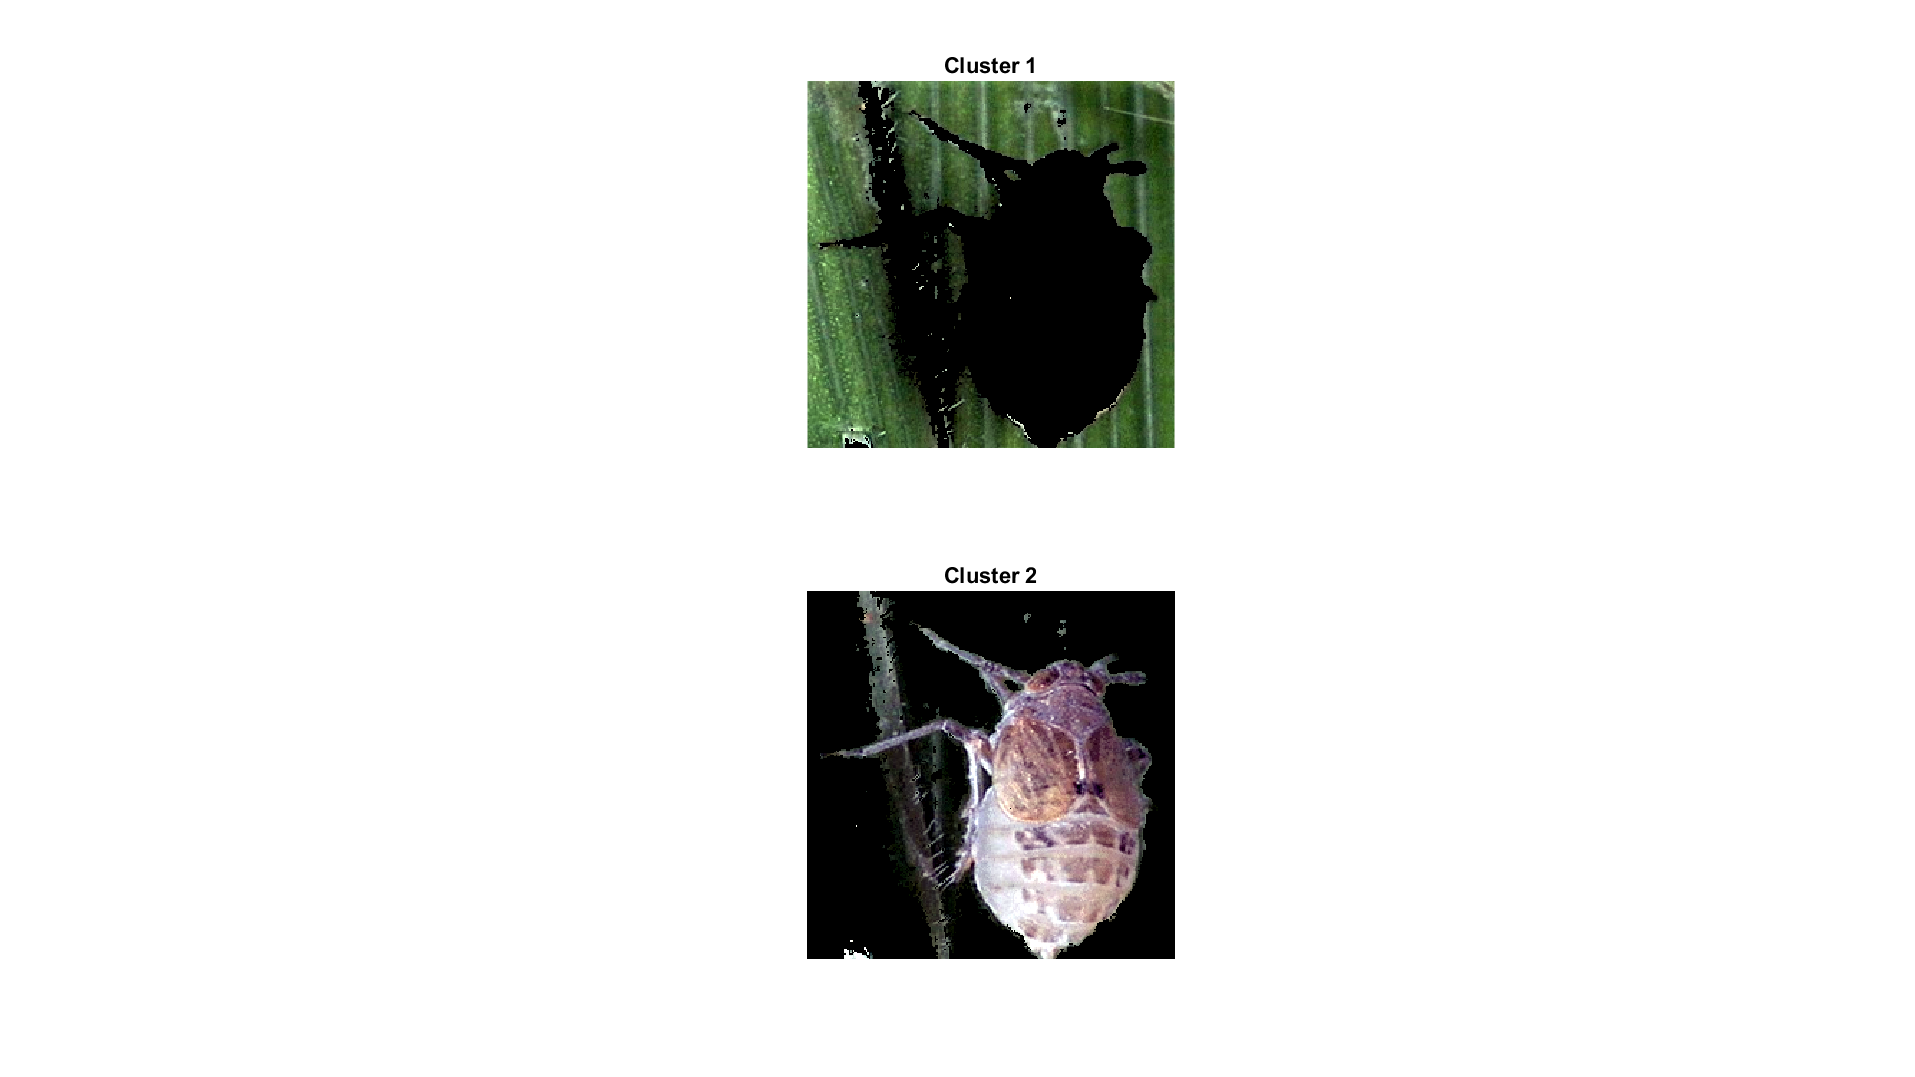

for k=1:2
    for j=1:8
        I = imread(sprintf('C:/Users/seren/OneDrive/Documents/MATLAB/EarlyPestDetection/Final/TrainPhase1/train%d_%d.png', k, j));
        I = imresize(I,[256,256]);
        I = imadjust(I,stretchlim(I));
        
        % Convert RGB image to L*a*b
        cform = makecform('srgb2lab'); % Create color transformation structure
        lab_he = applycform(I,cform); % Apply cform
        
        % Create matrix for k-means clustering
        ab = double(lab_he(:,:,2:3));
        nrows = size(ab,1);
        ncols = size(ab,2);
        ab = reshape(ab,nrows*ncols,2);
        nColors = 2;
        % Form two clusters using squared Euclidean distance
        [cluster_idx, cluster_center] = kmeans(ab,nColors,'distance','sqEuclidean','Replicates',2);
        
        % Reshape the clusters
        pixel_labels = reshape(cluster_idx,nrows,ncols);
        
        % Create a blank cell array to store the results of clustering
        segmented_images = cell(1,2);
        % Create RGB label using pixel_labels
        rgb_label = repmat(pixel_labels,[1,1,3]);
        
        for i = 1:nColors
            colors = I;
            colors(rgb_label ~= i) = 0;
            segmented_images{i} = colors;
        end
        
        figure, 
        subplot(2,1,1);imshow(segmented_images{1});title('Cluster 1'); 
        subplot(2,1,2);imshow(segmented_images{2});title('Cluster 2');
        set(gcf, 'Position', get(0,'Screensize'));
        
        % Feature Extraction
        x = inputdlg('Enter the cluster no. containing the ROI only:');
        xs = str2double(x);
        % Extract the features from the segmented image and remove
        % background
        seg_img = segmented_images{xs};
        val= max(seg_img,[],3); 
        mask=uint8(seg_img(:,:,2)~=val);
        seg_img = seg_img.*mask;

        destdirectory = 'C:/Users/seren/OneDrive/Documents/MATLAB/EarlyPestDetection/Final/TrainPhase2';
%         mkdir(destdirectory);
        baseFileName = sprintf('train%d_%d.png', k, j);
        fulldestination = fullfile(destdirectory, baseFileName);  %name file relative to that directory
        imwrite(seg_img, fulldestination);  %save the file there directory
    end
end

disp('Train 1 Complete');

Train 1 Complete


### **Train 2**

xx = [];
p=1;
Train_Feat = [];
for k=1:2
    for j=1:8
        I = imread(sprintf('C:/Users/seren/OneDrive/Documents/MATLAB/EarlyPestDetection/Final/TrainPhase2/train%d_%d.png', k, j));
        cform = makecform('srgb2lab');
        % Apply the colorform
        lab_he = applycform(I,cform);
        img = rgb2gray(lab_he); % Convert RBG image to gray scale
        glcms = graycomatrix(img); % Create gray scale matrix
        
        % Extract features
        stats = graycoprops(glcms,'Contrast Correlation Energy Homogeneity');

        Contrast = stats.Contrast;
        Correlation = stats.Correlation;
        Energy = stats.Energy;
        Homogeneity = stats.Homogeneity;
        ff = [Contrast, Correlation, Energy, Homogeneity];
        
        Train_Feat = [Train_Feat;ff];
        
        % Create label matrix
        if k==1 
            xx = [xx;1];
        elseif k==2
            xx = [xx;2];
        end
        Train_Label = xx.';
        Train_Label = transpose(xx);
    end
end
disp('Train 2 Complete');

Train 2 Complete


save('Train_Phase_Data.mat', 'Train_Feat', 'Train_Label');